# Spectrahedral Shadow

In CORA, spectrahedral shadows are instantiated by 

% SpS = spectraShadow(A,c,G);

where `A` is the horizontal concatenation of the coefficient matrices, `c` is the center vector, and `G` is the generator matrix.

Alternatively, a spectrahedral shadow can be instantiated as

% SpS = spectraShadow(E);

where `E` is a `1x2` cell array, where the first element is a matrix A that is the concatenation of the coefficient matrices, and the second element is a matrix `B` that is the concatenation of the additional coefficient matrices.

Example:

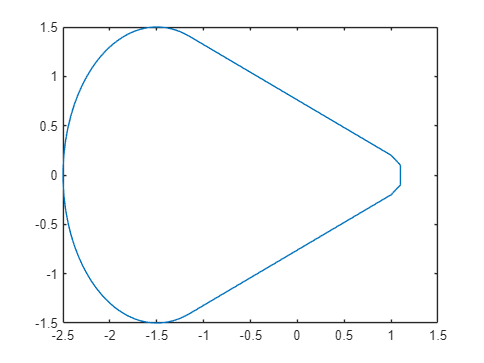

% init figure
figure;

% create two simple spectrahedral shadows
% an ellipsoid, using the first type of instantiation
A0 = eye(3);
A1 = [0 1 0; 1 0 0; 0 0 0];
A2 = [0 0 1; 0 0 0; 1 0 0];
A = [A0 A1 A2];
c = [-1.5;0];
G = [1 0;0 1.5];

SpS_ellipsoid = spectraShadow(A,c,G);

% a small zonotope, using the second type of instantiation
A0 = diag([-19 1 11 21 1 -9]);
A1 = diag([10 10 0 -10 -10 0]);
A2 = (10/3)*diag([1 -1 2 -1 1 -2]);
A = [A0 A1 A2];

B = 0.5774*diag([-1 1 1 1 -1 -1]);

ESumRep = {A, B};

SpS_zonotope = spectraShadow(ESumRep);

% we can construct more complicated sets
% based on the two above, such as the
% convex hull of the two previous spectrahedral shadows
SpS = convHull(SpS_ellipsoid, SpS_zonotope);

% plot spectraShadow
plot(SpS);